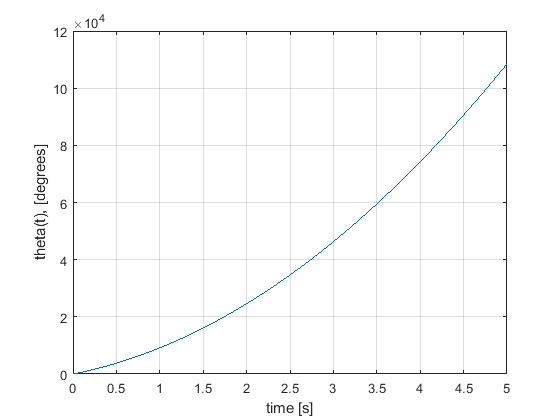


clear all
close all 

R=0.17;
r=0.04;
m=1;
J=0.5;
klambda=0.004;
Initspeedtheta=(1000)*2*pi/60;
Initposabsorber=(0)/180*pi;
n=sqrt((r*R)/(r^2+klambda^2));
t0=0;
tf=5; 
y0=[0 Initspeedtheta Initposabsorber 0];
tspan=[t0 tf];
[t,y]=ode45('dynsystem',tspan,y0);
theta=y(:,1);
thetadot=y(:,2);    
phi=y(:,3); 
phidot=y(:,4);
figure(1) % Plot rotor angle
plot(t,theta/pi*180), grid
xlabel('time [s]')
ylabel('theta(t), [degrees]')

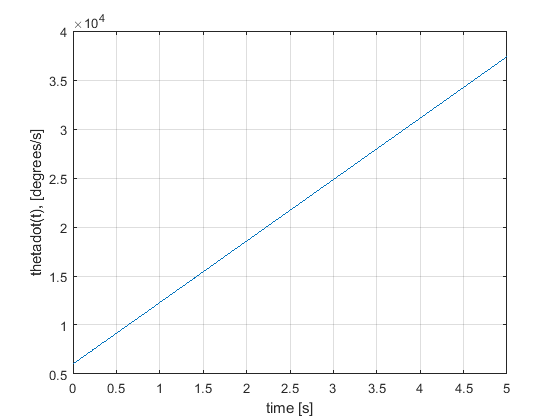

figure(2) % Plot rotor angular speed
plot(t,thetadot/pi*180), grid
xlabel('time [s]')
ylabel('thetadot(t), [degrees/s]')

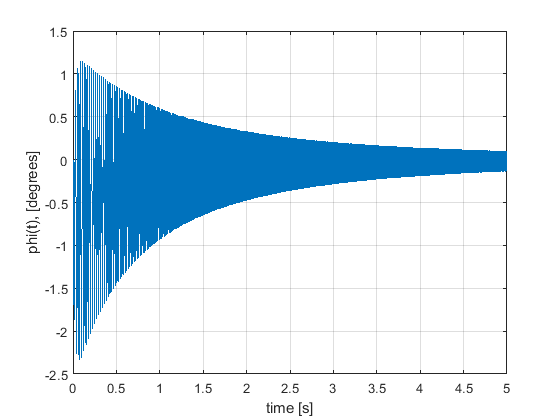

figure(3) % Plot absorber angle
plot(t,phi/pi*180), grid
xlabel('time [s]')
ylabel('phi(t), [degrees]')

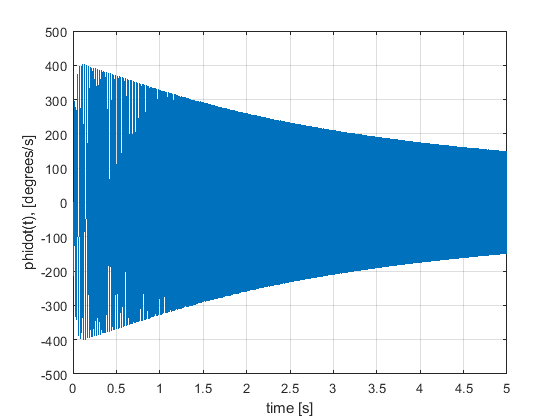

figure(4) % Plot absorber angular speed
plot(t,phidot/pi*180), grid
xlabel('time [s]')
ylabel('phidot(t), [degrees/s]')

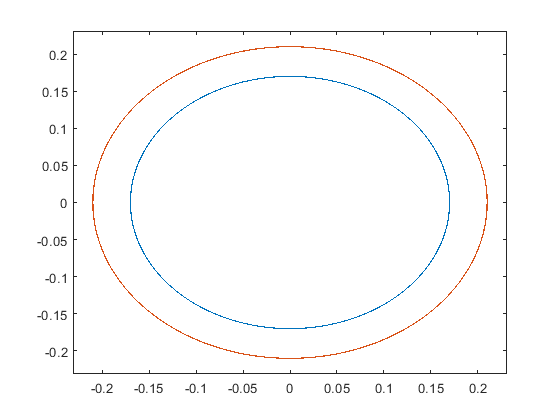

% Calculate positions of absorber attachment point on rotor
x1=R.*sin(theta);
y1=-R.*cos(theta);
% Calculate positions for absorber centre of mass
x2=R.*sin(theta)+r.*sin(theta+phi);
y2=-R.*cos(theta)-r.*cos(theta+phi);
% Plot the above positions
figure(5)
plot(x1,y1)
hold on
plot(x2,y2)
axis([-(R+r)*1.1 (R+r)*1.1 -(R+r)*1.1 (R+r)*1.1])